# `Simple Simscape vehicle longitudinal dynamics in Simscape`

clear
clc

Vehicle Parameters



%% Kia EV6 RWD
M_1 = 4500 * 0.453592;                                % vehicle mass (kg) Kia EV 6 
F0_1 = 26.163 * 0.4535924*9.81;                       % Target Coef F0 (N) 26.163	0.18798	0.020147
F1_1 = 0.18798 * 0.4535924*9.81 * (3600/1609.34);     % Target Coef F1 (N/m/s)
F2_1 = 0.020147 * 0.4535924*9.81 * (3600/1609.34)^2;  % Target Coef F2 (N/(m/s)^2)

%% Tesla Model Y RWD 
M_2 = 4500 * 0.453592;                                % vehicle mass (kg) Tesla Model Y Performance RWD
F0_2 = 30.980 * 0.4535924*9.81;                       % Target Coef F0 (N) 30.980	0.15960	0.014100
F1_2 = 0.15960 * 0.4535924*9.81*(3600/1609.34);       % Target Coef F1 (N/m/s)
F2_2 = 0.014100 * 0.4535924*9.81*(3600/1609.34)^2;    % Target Coef F2 (N/(m/s)^2)

%% Mahindra BE 6 
M_3 = 2415;
F0_3 = 295.8371;                          % F0 (N) Refer Fit_cal
F1_3 = 0.1155;                            % F1: N/(m/s)
F2_3 = 0.4567;                            % F2: N/(m/s)^2

Inputs

% Define the velocity range from 0 to 180 kph
velocity_kph = linspace(0, 120, 500);
% Convert velocity from kph to m/s for the road load equation
velocity_mps = velocity_kph * (1000 / 3600);


% Calculate road load tractive effort (F_road = F0 + F1*v + F2*v^2)
% Note: Using element-wise operators (.* and .^) for vector calculations
tractive_effort_1 = F0_1 + F1_1 .* velocity_mps + F2_1 .* velocity_mps.^2;
tractive_effort_2 = F0_2 + F1_2 .* velocity_mps + F2_2 .* velocity_mps.^2;
tractive_effort_3 = F0_3 + F1_3 .* velocity_mps + F2_3 .* velocity_mps.^2;

Plot Results

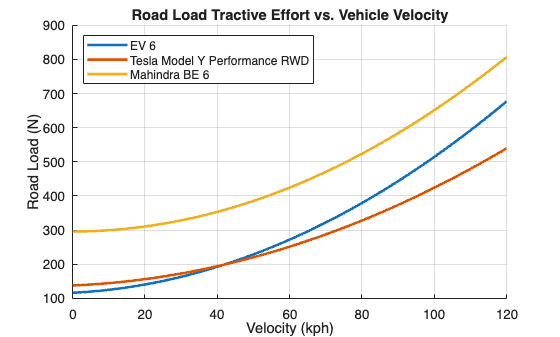

% Create the plot
figure; % Create a new figure window
hold on; % Allow multiple lines on the same plot

% Plot the data for each vehicle
plot(velocity_kph, tractive_effort_1, 'LineWidth', 2);
plot(velocity_kph, tractive_effort_2, 'LineWidth', 2);
plot(velocity_kph, tractive_effort_3, 'LineWidth', 2);


hold off; % Release the plot

% Add labels, title, legend, and grid for clarity
title('Road Load Tractive Effort vs. Vehicle Velocity');
legend('EV 6', 'Tesla Model Y Performance RWD','Mahindra BE 6', Location='northwest');
xlabel('Velocity (kph)');
ylabel('Road Load (N)');
xlim("auto")
ylim("auto")
grid on; % Add grid for better visualization